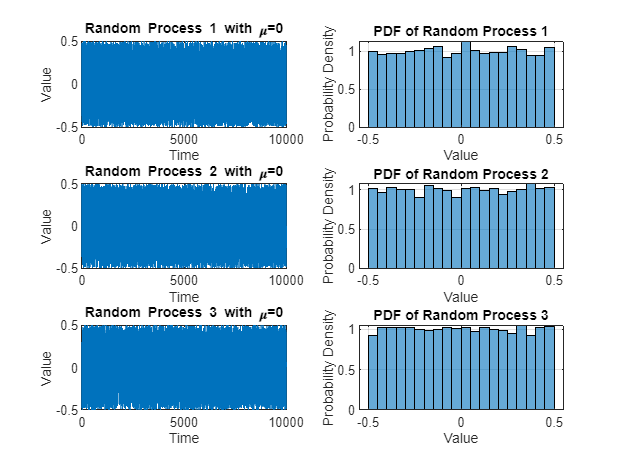

Random Process 1 - Mean: 0.0013252, Variance: 0.082786
Random Process 2 - Mean: 0.0021248, Variance: 0.084013
Random Process 3 - Mean: 3.0132e-05, Variance: 0.083143


clear all; close all; clc;

num_samples = 10000;  % Number of samples
num_simulations = 3; % Number of simulations (random processes)
length_data = 1000;   % Number of time instances

% Generate the time axis (x-axis)
time_axis = 1:num_samples;

% Initialize matrix to store simulation data
simulation_data = zeros(num_simulations, num_samples);

% Generate simulation data
for sim = 1:num_simulations
    % Generate random samples from a uniform distribution between -0.5 and 0.5
    random_samples = rand(1, num_samples) - 0.5;
    simulation_data(sim, :) = random_samples;
end

% Plot the random processes and calculate their mean and variance
figure;
for sim = 1:num_simulations
    subplot(num_simulations, 2, 2*sim - 1);
    plot(time_axis, simulation_data(sim, :));
    xlabel('Time');
    ylabel('Value');
    title(['Random Process ', num2str(sim) ' with \mu=0']);
    grid on;
    
    % Calculate and display mean and variance
    process_mean = mean(simulation_data(sim, :));
    process_variance = var(simulation_data(sim, :));
    disp(['Random Process ', num2str(sim), ' - Mean: ', num2str(process_mean), ', Variance: ', num2str(process_variance)]);
    
    % Plot the histogram and probability density curve
    subplot(num_simulations, 2, 2*sim);
    histogram(simulation_data(sim, :), 'Normalization', 'pdf');
    xlabel('Value');
    ylabel('Probability Density');
    title(['PDF of Random Process ', num2str(sim)]);
    grid on;
end


% Calculate Ensemble Averages for specific time instances
time_instants = [1, 100, 1000]; % Specific time instances for analysis
ensemble_averages = mean(simulation_data(:, time_instants), 1);

% Display Ensemble Averages
disp('Ensemble Averages:');

Ensemble Averages:


for i = 1:length(time_instants)
    fprintf('At time instance %d: %f\n', time_instants(i), ensemble_averages(i));
end

At time instance 1: 0.038166
At time instance 100: 0.044562
At time instance 1000: 0.103993
